### Gamma at origin

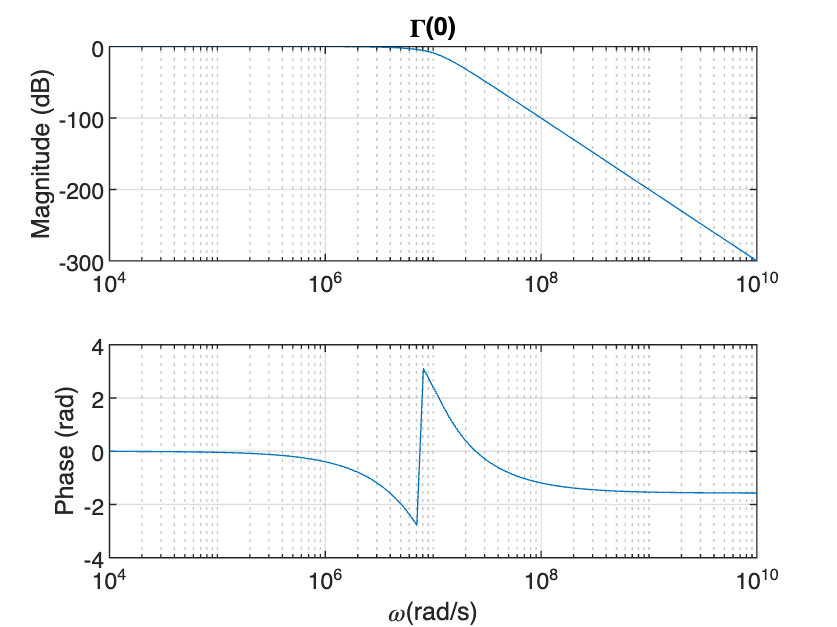

[b,a] = besself(5,1e7);
[Gamma0,w] = freqs(b,a,logspace(4, 10, 1e2));
figure;
plot_resp_logy(w, Gamma0, '\Gamma(0)')

### Plotting $\phi(y)$

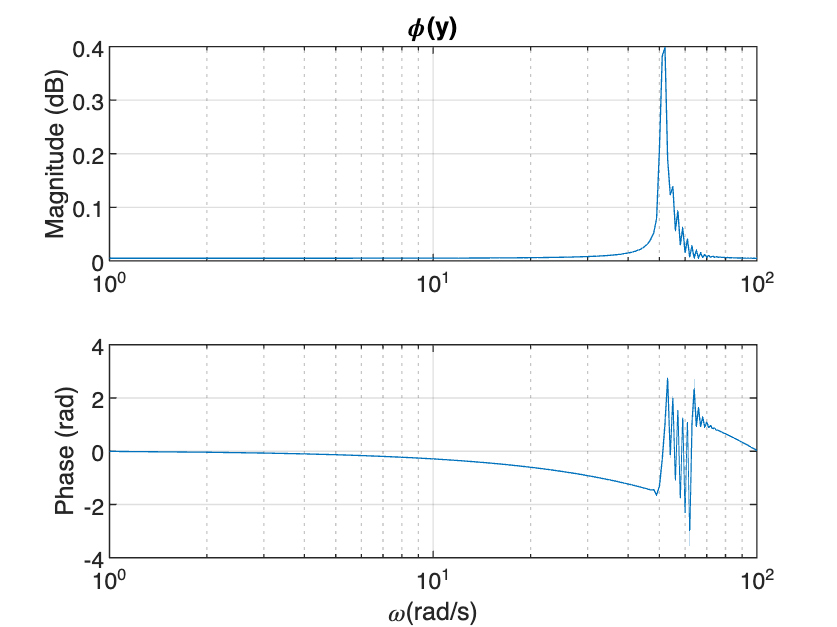

phiy = ifftshift(ifft(Gamma0));
figure
plot_resp(1:1:length(Gamma0), phiy, "\phi(y)")

Solving for $y$

Functions

function plot_resp_logy(x, y, name) % plot functions with dB in y
    subplot(2, 1, 1)
    semilogx(x, 20*log(abs(y))/log(10))
    title(name)
    ylabel("Magnitude (dB)")
    grid("on")
    subplot(2, 1, 2)
    semilogx(x, angle(y))
    ylabel("Phase (rad)")
    xlabel("\omega(rad/s)")
    grid("on")
end

function plot_resp(x, y, name) % plot functions
    subplot(2, 1, 1)
    semilogx(x, abs(y))
    title(name)
    ylabel("Magnitude (dB)")
    grid("on")
    subplot(2, 1, 2)
    semilogx(x, angle(y))
    ylabel("Phase (rad)")
    xlabel("\omega(rad/s)")
    grid("on")
end

function plot_switch_comparison(w, Gamma0, Gamma_on, Gamma_off)
    subplot(3, 1, 1)
    semilogx(w, 20*log(abs(Gamma0))/log(10))
    ylabel("\Gamma(\omega, z=0)")
    grid("on")
    subplot(3, 1, 2)
    semilogx(w, 20*log(abs(Gamma_on))/log(10))
    ylabel("\Gamma_{on}(\omega)")
    grid("on")
    subplot(3, 1, 3)
    semilogx(w, 20*log(abs(Gamma_off))/log(10))
    ylabel("\Gamma_{off}(\omega)")
    grid("on")
    xlabel("\omega(rad/s)")
end